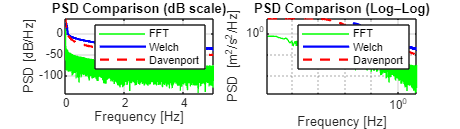

clc; clear; close all;

%% ---------------- Step 1: Load and Clean Wind Data ---------------- %%
A = importdata('31Oct2024.dat');
wind_speed = A.data(:,1);  

% Remove NaN and bad values
valid_idx = ~isnan(wind_speed) & wind_speed > 0;
wind_clean = wind_speed(valid_idx);

% Median filter (despiking)
wind_despiked = medfilt1(wind_clean, 5);

% Remove ±3σ outliers
mean_wind = mean(wind_despiked);
std_wind = std(wind_despiked);
upper_limit = mean_wind + 3 * std_wind;
lower_limit = mean_wind - 3 * std_wind;
wind_final = wind_despiked(wind_despiked >= lower_limit & wind_despiked <= upper_limit);

%% ---------------- Step 2: FFT-based PSD ---------------- %%
Fs = 10;  % Sampling frequency (Hz)
N = length(wind_final);
Y = fft(wind_final);
P2 = abs(Y/N).^2;               % Two-sided power
P1 = P2(1:floor(N/2)+1);        % One-sided power
P1(2:end-1) = 2*P1(2:end-1);    % Energy correction
f_fft = Fs*(0:floor(N/2))/N;    % Frequency vector (Hz)

%% ---------------- Step 3: Welch-based PSD ---------------- %%
window = hamming(256);
noverlap = 128;
nfft = 512;
[pxx_welch, f_welch] = pwelch(wind_final, window, noverlap, nfft, Fs);

%% ---------------- Step 4: Davenport Spectrum ---------------- %%
U = mean_wind;      % Mean wind speed from cleaned data
z = 23.16;          % Height (m)
z0 = 0.03;          % Roughness length (m)
b = 600 / (pi * U);
k = (1 / (2.5 * log(z / z0)))^2;

% Match Davenport freq vector to FFT/Welch resolution
f_dav = f_fft;  
w_dav = 2*pi*f_dav;
Sv_dav = (4800 * U * b * k) ./ ((1 + (b^2) * w_dav.^2).^(4/3));

%% ---------------- Step 5: Ensure Units Match ---------------- %%
% FFT and Welch already give linear PSD in [m^2/s^2/Hz]
% Davenport is also in [m^2/s^2/Hz] now (linear scale)
% For dB plot: 10*log10(PSD)

%% ---------------- Step 6: Plot Both Scales ---------------- %%
figure('Units','normalized','Position',[0.1 0.1 0.8 0.4]);

% ---- Left: dB scale ----
subplot(1,2,1);
plot(f_fft, 10*log10(P1), 'g'); hold on;
plot(f_welch, 10*log10(pxx_welch), 'b', 'LineWidth', 1.5);
plot(f_dav, 10*log10(Sv_dav), 'r--', 'LineWidth', 1.5);
grid on;
xlabel('Frequency [Hz]');
ylabel('PSD [dB/Hz]');
title('PSD Comparison (dB scale)');
legend('FFT','Welch','Davenport');
xlim([min(f_fft) max(f_fft)]);

% ---- Right: log–log linear PSD ----
subplot(1,2,2);
loglog(f_fft, P1, 'g'); hold on;
loglog(f_welch, pxx_welch, 'b', 'LineWidth', 1.5);
loglog(f_dav, Sv_dav, 'r--', 'LineWidth', 1.5);
grid on;
xlabel('Frequency [Hz]');
ylabel('PSD [m^2/s^2/Hz]');
title('PSD Comparison (Log–Log)');
legend('FFT','Welch','Davenport');
xlim([min(f_fft(f_fft>0)) max(f_fft)]);